clear
clc
spec='finExp';
bag_30Front = rosbag('front_30.bag');
bag_35Front = rosbag('front_35.bag');
bag_40Front = rosbag('front_40.bag');

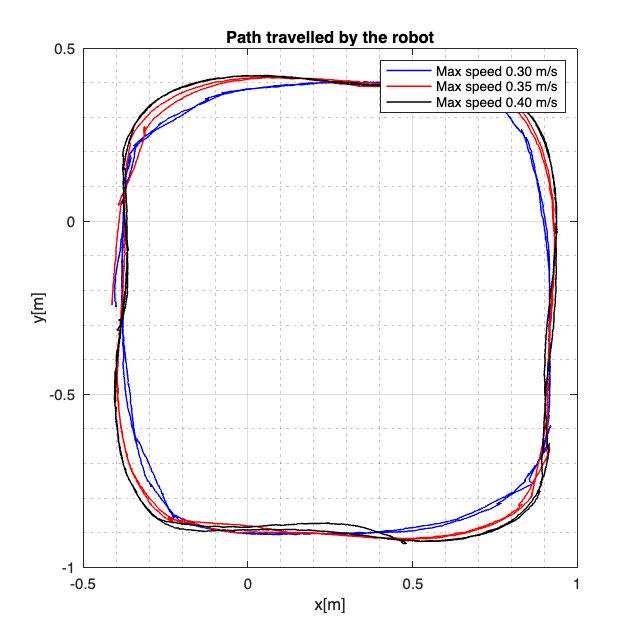

odom.front30 = select(bag_30Front,'Topic',"/turtlebot_05/odom");
odom.front35 = select(bag_35Front,'Topic',"/turtlebot_05/odom");
odom.front40 = select(bag_40Front,'Topic',"/turtlebot_05/odom");

odomData.front30 = timeseries(odom.front30,'Pose.Pose.Position.X','Pose.Pose.Position.Y').Data;
odomData.front35 = timeseries(odom.front35,'Pose.Pose.Position.X','Pose.Pose.Position.Y').Data;
odomData.front40 = timeseries(odom.front40,'Pose.Pose.Position.X','Pose.Pose.Position.Y').Data;
%plotting data
figure
hold on
grid on
grid minor
box on
xlabel("x[m]")
ylabel("y[m]")
title("Path travelled by the robot")
%xlim([0,5.5])
%ylim([0,3.5])

plot(odomData.front30(:,1),odomData.front30(:,2), LineWidth=1,Color='b')
plot(odomData.front35(:,1),odomData.front35(:,2), LineWidth=1,Color='r')
plot(odomData.front40(:,1),odomData.front40(:,2), LineWidth=1,Color='k')



t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,15,15];
legend("Max speed 0.30 m/s", "Max speed 0.35 m/s", "Max speed 0.40 m/s")

%exportgraphics(t,strcat(spec,'odom2','.png'),'Resolution',600)

writematrix(odomData.front30, "front30.csv")
writematrix(odomData.front35, "front35.csv")
writematrix(odomData.front40, "front40.csv")


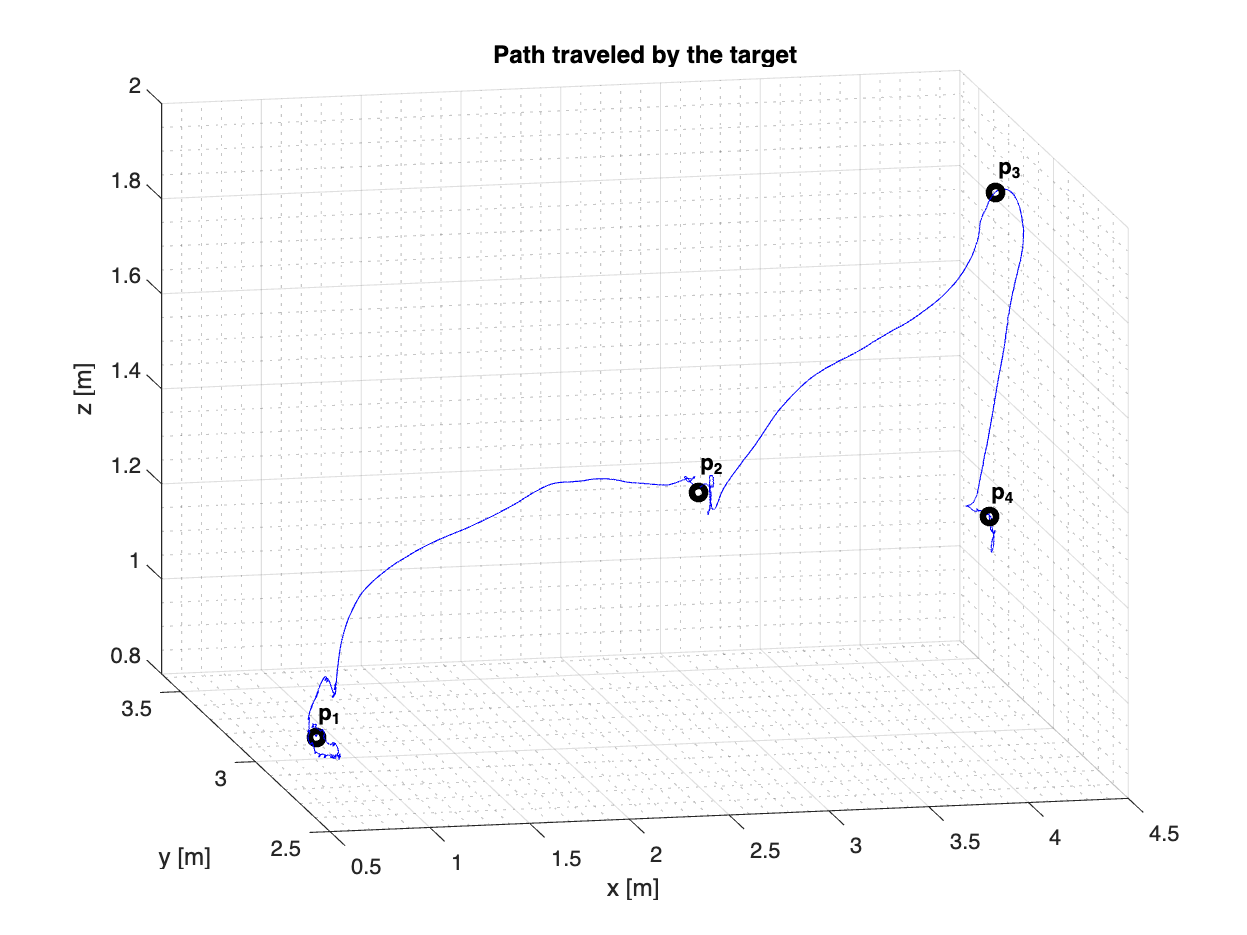


ss = select(bag_30Front,'Topic',"/vicon/qav250_01");

aaa = readMessages(ss,'DataFormat','struct');
[x,y,z] = cellfun(@getOdomPos, aaa(1600:end-10000));
th = 0.1;
dim = size(x);
for i = 1:dim(:,1)-1
    %if(dist(x(i),x(i+1),y(i),y(i+1))>th)
    if(x(i+1)==0)
       x(i+1) = x(i);
       y(i+1) = y(i);
    end
end
figure
hold on
grid minor
grid on
%lot3(rotMeas(1:end-2000,1)-0.03,rotMeas(1:end-2000,2)-0.04,originalOdomTs.Time(1:end-2000))
plot3(x,y,z,Color='b')
plot3(0.67,2.82,0.9,"o", LineWidth=3, Color='k')
plot3(3.08,3.48,1.18,"o", LineWidth=3, Color='k')
plot3(4.12,2.88,1.97,"o", LineWidth=3, Color='k')
plot3(4.23,3.07,1.23,"o", LineWidth=3, Color='k')
text(0.67,2.82,0.95,"p_1","FontWeight","bold")
text(3.08,3.48,1.24,"p_2","FontWeight","bold")
text(4.12,2.88,2.02,"p_3","FontWeight","bold")
text(4.23,3.07,1.28,"p_4","FontWeight","bold")
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
title("Path traveled by the target")

view([-11.91 15.77])

t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,20,15];
exportgraphics(t,strcat(spec,'targetPose','.png'),'Resolution',600)

joint_states = select(bag_30Front,"Topic","/locobot/joint_states");
js_msg = readMessages(joint_states,'DataFormat','struct');
joint_commands = select(bag_30Front,"Topic","/locobot/commands/joint_group");
jc_msg = readMessages(joint_commands,'DataFormat','struct');
lm=4000; %4000
% Use struct message format for faster read time
[waistC,shoulderC,elbowC,wristC] = cellfun(@getJointsFromPointCommand, jc_msg(1:end-lm));
[waistS,shoulderS,elbowS,wristS] = cellfun(@getJointsFromPoint, js_msg(1:end-lm));

%plot(waistS)
js_time = joint_states.timeseries.Time(1:end-lm);
jc_time = joint_commands.MessageList.Time(1:end-lm);
js_time = js_time-js_time(1);
jc_time = jc_time-jc_time(1);

sizeX = 20;
sizeY = 5.75;

# **Shoulder Joint**

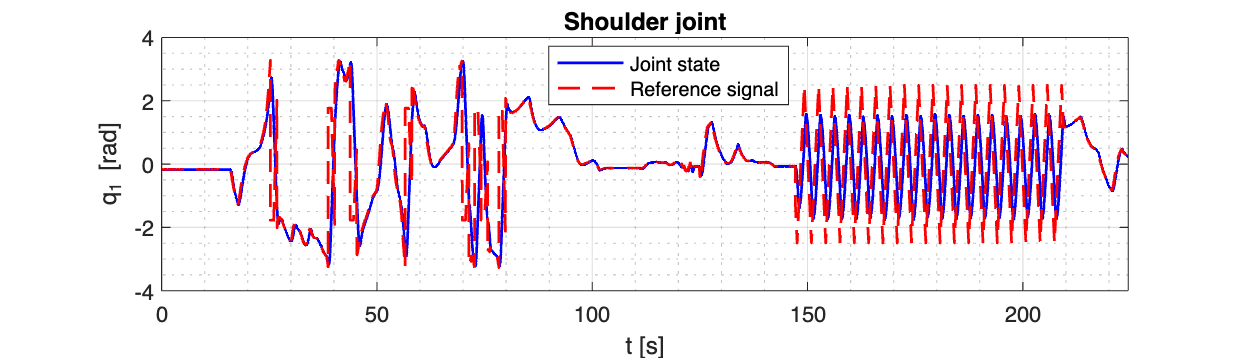


stateSignal = timeseries(waistS,js_time);
controlSignal = timeseries(waistC,jc_time);
figure
hold on
grid on
grid minor
box on
xlim('tight')
xlabel("t [s]")
ylabel("q_1 [rad]")
title("Shoulder joint")
plot(stateSignal(:,1),"LineWidth",1.25,"Color","Blue")
plot(controlSignal(:,1),"Color","Red","LineStyle","- -","LineWidth",1.25)
%plotPatches(0.2,target_z_ts(:,1).Time,min(ylim),max(ylim))
legend("Joint state","Reference signal")
legend("Position", [0.45, 0.75,0.1725,0.082812])
%saveas(gcf,"waist_joint","png")

t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeX,sizeY];
exportgraphics(t,strcat(spec,'shoulder','.png'),'Resolution',600)

# **Upperarm Joint**

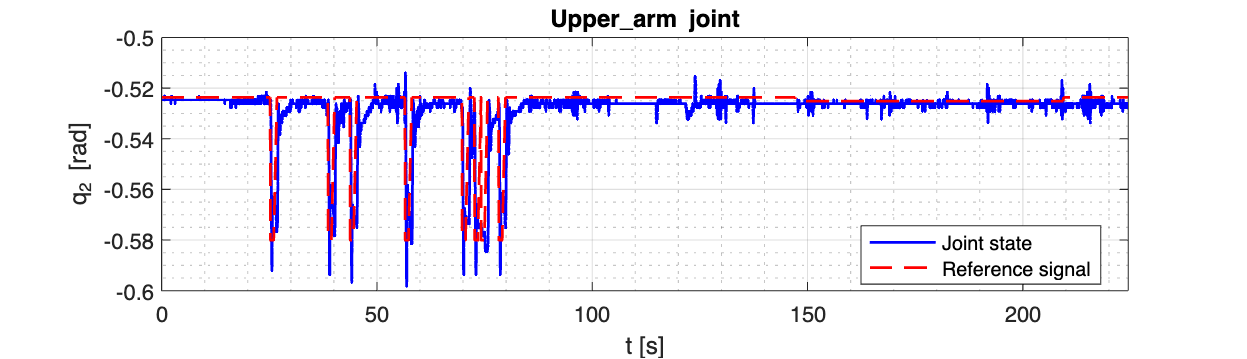

stateSignal = timeseries(shoulderS,js_time);
controlSignal = timeseries(shoulderC,jc_time);
figure
hold on
grid on
grid minor
box on
xlim('tight')
xlabel("t [s]")
ylabel("q_2 [rad]")
title("Upper\_arm joint")
plot(stateSignal(:,1),"LineWidth",1.25,"Color","Blue")
plot(controlSignal(:,1),"Color","Red","LineStyle","- -","LineWidth",1.25)
legend("Joint state","Reference signal")
legend("Position", [0.7, 0.25,0.1725,0.082812])
%saveas(gcf,"shoulder_joint","png")

t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeX,sizeY];
exportgraphics(t,strcat(spec,'upperarm','.png'),'Resolution',600)

# **Forearm Joint**

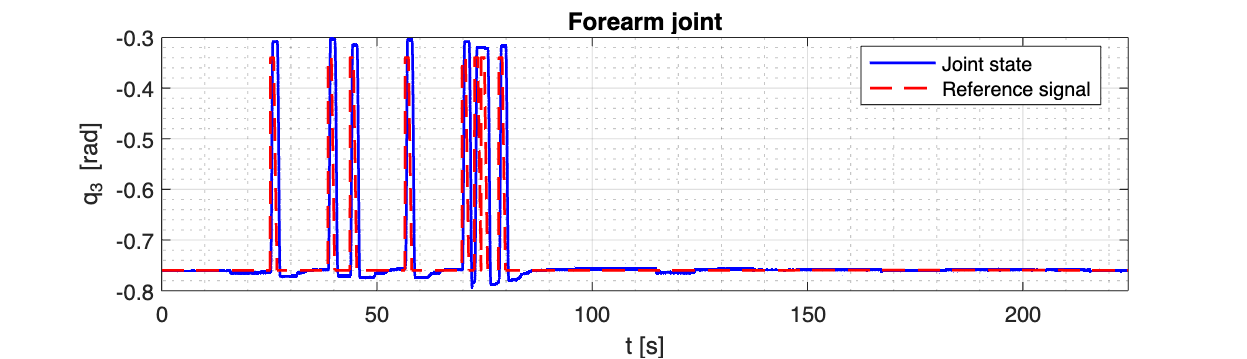

stateSignal = timeseries(elbowS,js_time);
controlSignal = timeseries(elbowC,jc_time);
figure
hold on
grid on
grid minor
box on
xlim('tight')
xlabel("t [s]")
ylabel("q_3 [rad]")
title("Forearm joint")
plot(stateSignal(:,1),"LineWidth",1.25,"Color","Blue")
plot(controlSignal(:,1),"Color","Red","LineStyle","- -","LineWidth",1.25)
legend("Joint state","Reference signal")
legend("Position", [0.7, 0.75,0.1725,0.082812])
%saveas(gcf,"elbow_joint","png")

t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeX,sizeY];
exportgraphics(t,strcat(spec,'forearm','.png'),'Resolution',600)

# **Wrist Angle Joint**

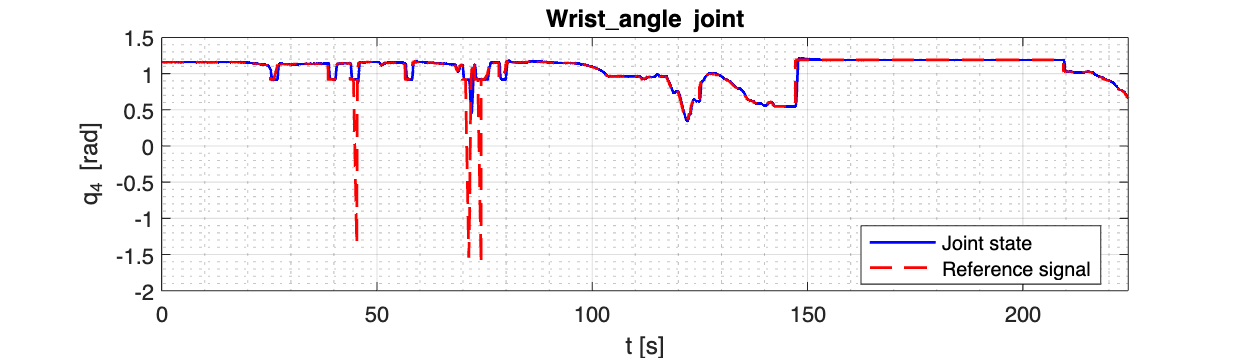

stateSignal = timeseries(wristS,js_time);
controlSignal = timeseries(wristC,jc_time);
figure
hold on
grid on
grid minor
box on
xlim('tight')
xlabel("t [s]")
ylabel("q_4 [rad]")
title("Wrist\_angle joint")
plot(stateSignal(:,1),"LineWidth",1.25,"Color","Blue")
plot(controlSignal(:,1),"Color","Red","LineStyle","- -","LineWidth",1.25)
legend("Joint state","Reference signal")
legend("Position", [0.7, 0.25,0.1725,0.082812])
%saveas(gcf,"wrist_joint","png")

t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeX,sizeY];
exportgraphics(t,strcat(spec,'wristAngle','.png'),'Resolution',600)

%3d graph for target
targetPos = select(bag_30Front,"Topic","/target/pose_cam");
tp_msgs = readMessages(targetPos,'DataFormat','struct');
lm = 750; %750
[target_x,target_y,target_z] = cellfun(@getTargetPosCam, tp_msgs(1:end-lm));
sizeXT = 32;
sizeYT = 7.25;



target_time = targetPos.timeseries.Time(1:end-lm);
target_time = target_time-target_time(1);
target_x_ts = timeseries(target_x,target_time);
target_y_ts = timeseries(target_y,target_time);
target_z_ts = timeseries(target_z,target_time);
thresh = 0.31;

# Target on x axis

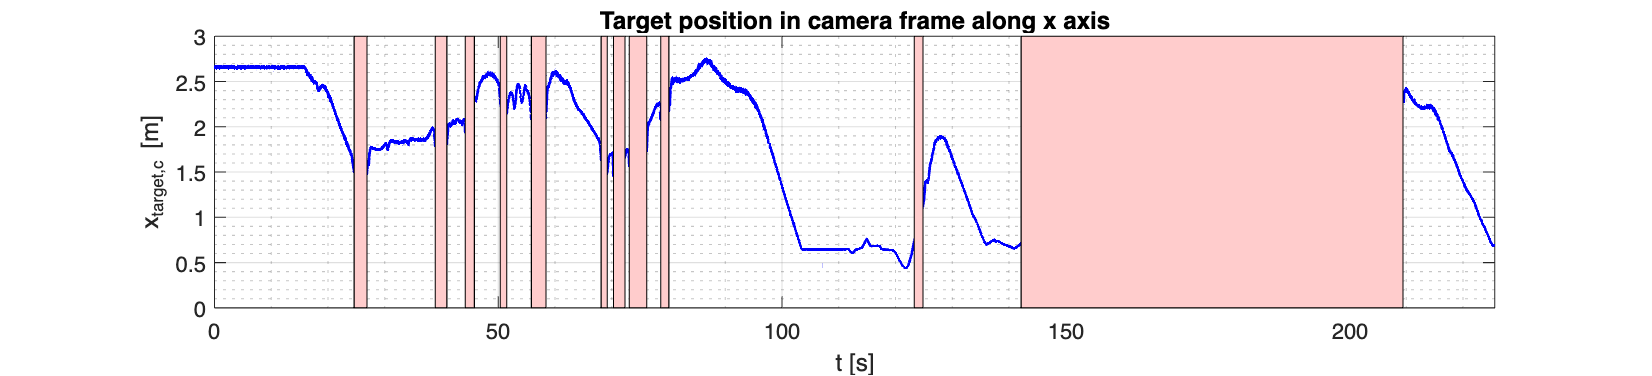

figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")
ylabel("x_{target,c} [m]")
title("Target position in camera frame along x axis")
plot(target_z_ts(:,1),"LineWidth",1.2,"Color","Blue")
plotPatches(thresh,target_z_ts(:,1).Time,min(ylim),max(ylim),'red',0.2)
%stairs(target_z_ts(:,1).Time,target_z_ts(:,1).Data,LineStyle="-")
%stairs(target_z_ts(:,1).Time(temp),target_z_ts(:,1).Data(temp),'or')
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,sizeYT];
exportgraphics(t,strcat(spec,'camX','.png'),'Resolution',600)

# Target on y axis

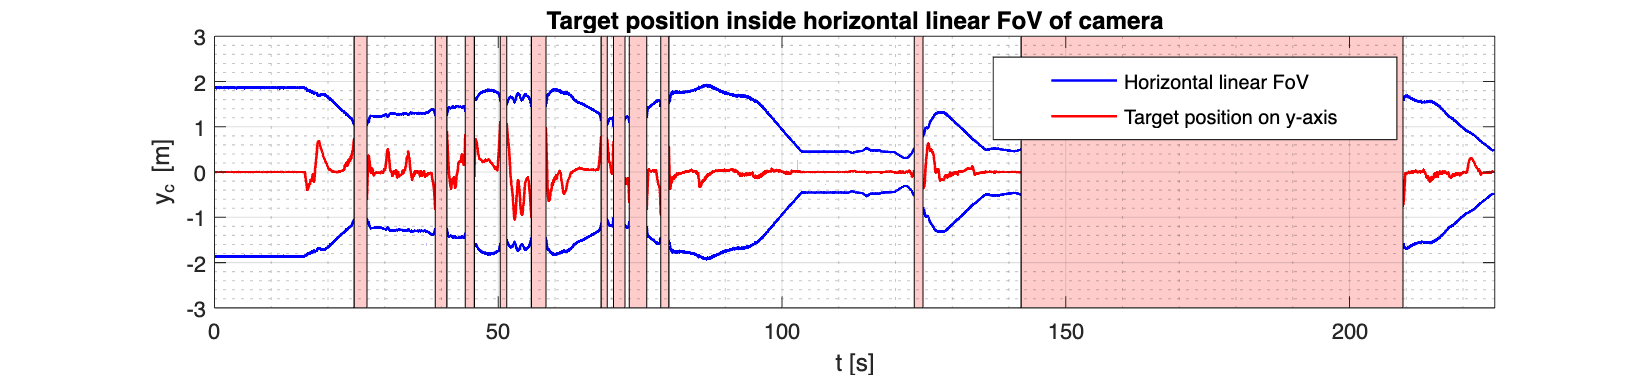

angle = 35*pi/180;
c2 = target_z_ts.Data*tan(angle);

figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")
ylabel("y_{c} [m]")
ylim([-3;3])
title("Target position inside horizontal linear FoV of camera")
plot(target_x_ts.Time,[c2,-c2], Color='Blue', LineWidth=1.2)
plot(target_x_ts(:,1)*(-1)+target_x_ts.Data(1),"LineWidth",1.2,"Color","Red")
%plotPatches(thresh,target_z_ts(:,1).Time,min(ylim),max(ylim),'white',1)
ax = gca;
ax.Layer='top';
plotPatches(thresh,target_z_ts(:,1).Time,min(ylim),max(ylim),'red',0.2)
legend('Horizontal linear FoV','','Target position on y-axis')
legend("Position", [0.60086,0.62893,0.24515,0.22083])
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,sizeYT];
exportgraphics(t,strcat(spec,'camY','.png'),'Resolution',600)

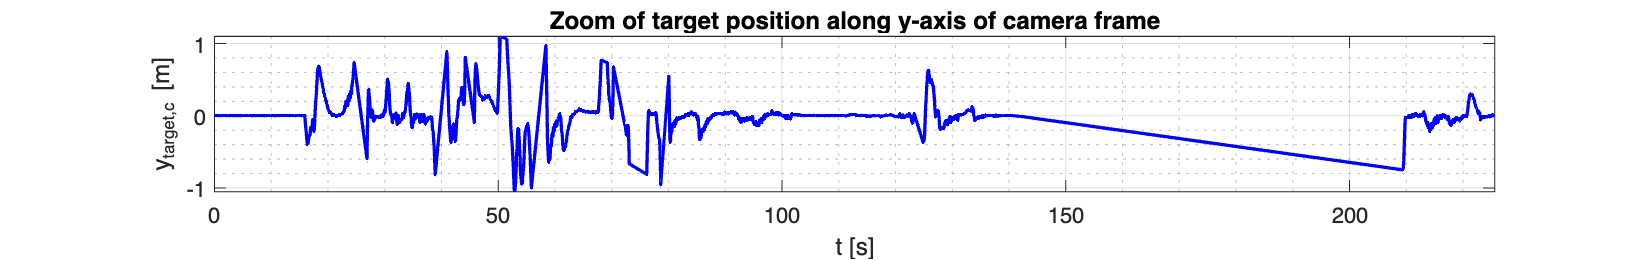






figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")

ylabel("y_{target,c} [m]")
title("Zoom of target position along y-axis of camera frame")
plot(target_x_ts(:,1)*(-1)+target_x_ts.Data(1),"LineWidth",1.5,"Color",'Blue')
%legend('Horizontal linear FoV','','Target position along y-axis')
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,5];
exportgraphics(t,strcat(spec,'camYzoom','.png'),'Resolution',600)

# Target on z axis

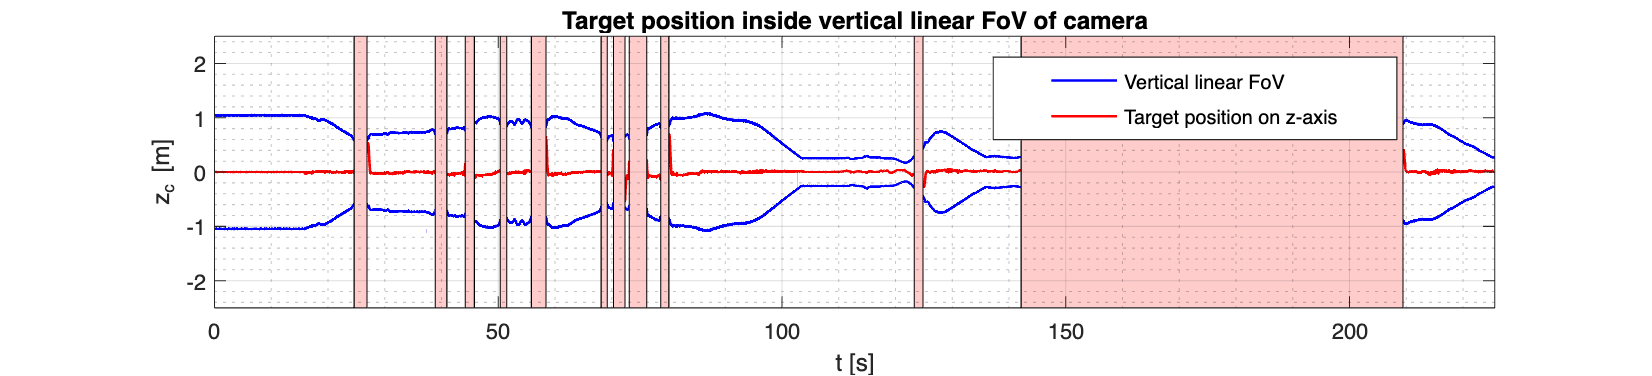

angle = 21.5*pi/180;
c2 = target_z_ts.Data*tan(angle);

figure
hold on
box on
grid on
grid minor
xlim('tight')
ylim([-2.5;2.5])
xlabel("t [s]")
ylabel("z_{c} [m]")
title("Target position inside vertical linear FoV of camera")
plot(target_x_ts.Time,[c2,-c2], Color='Blue', LineWidth=1.2)
plot(target_y_ts(:,1)*(-1)+target_y_ts.Data(1),"LineWidth",1.2,"Color","Red")
%plotPatches(thresh,target_z_ts(:,1).Time,min(ylim),max(ylim),'white',1)
ax = gca;
ax.Layer='top';
plotPatches(thresh,target_z_ts(:,1).Time,min(ylim),max(ylim),'red',0.2)
legend('Vertical linear FoV','','Target position on z-axis')
legend("Position", [0.60086,0.62893,0.24515,0.22083])
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,sizeYT];
exportgraphics(t,strcat(spec,'camZ','.png'),'Resolution',600)

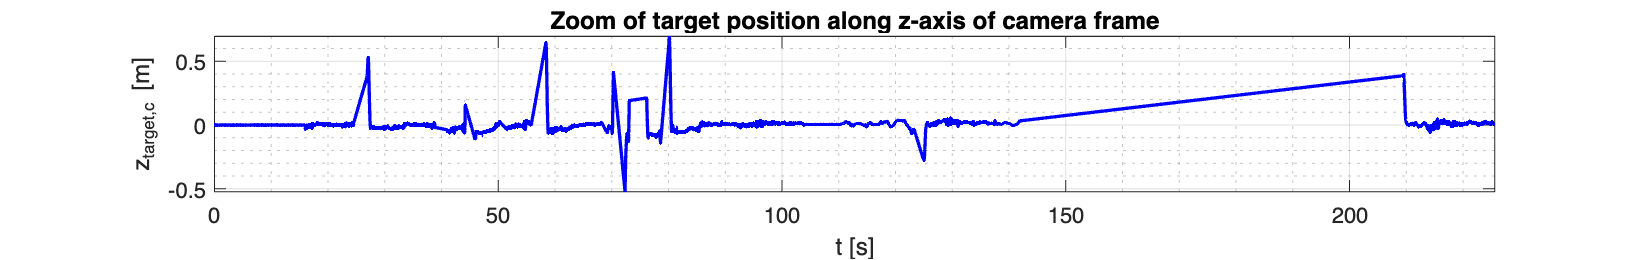


figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")

ylabel("z_{target,c} [m]")
title("Zoom of target position along z-axis of camera frame")
plot(target_y_ts(:,1)*(-1)+target_y_ts.Data(1),"LineWidth",1.5,"Color",'Blue')
%legend('Horizontal linear FoV','','Target position along y-axis')
grid on
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,5];
exportgraphics(t,strcat(spec,'camZzoom','.png'),'Resolution',600)

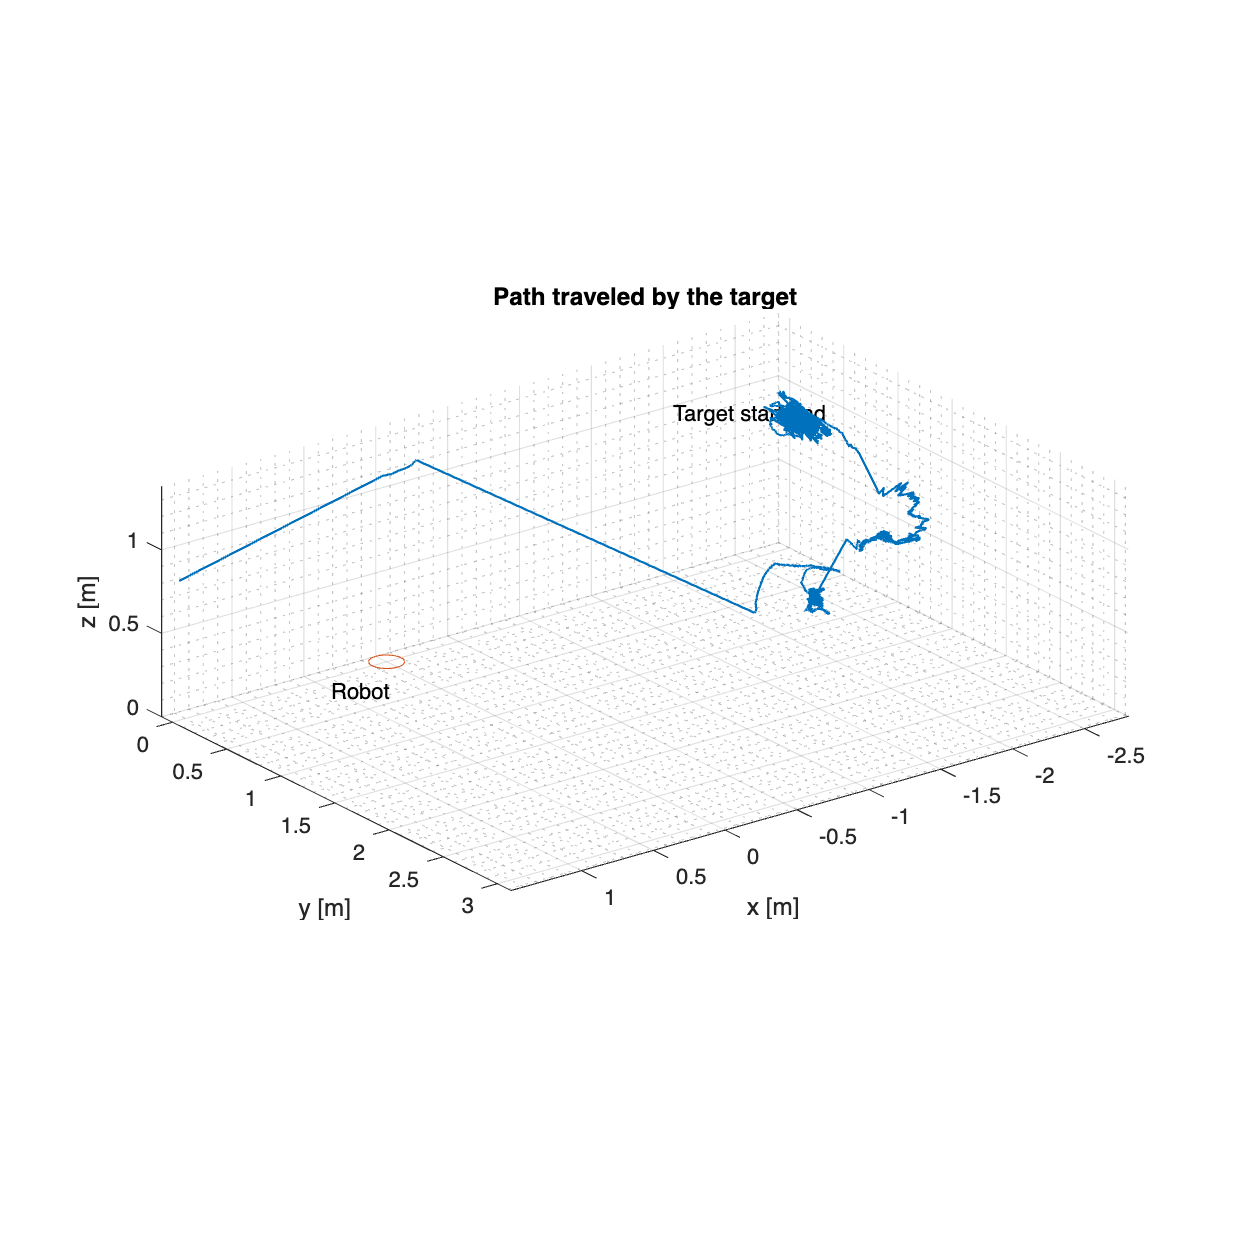

targetPos = select(bag_30Front,"Topic","/target/pose_bot");
tp_msgs = readMessages(targetPos,'DataFormat','struct');
[target_x,target_y,target_z] = cellfun(@getTargetPos, tp_msgs);
figure
view(3)

plot3(target_x,target_y,target_z, LineStyle="-", LineWidth=1.0)
circle(0,0,0.1);
grid minor
grid on
axis equal
%xlim([-4,1])
%ylim([-4,1])
text(0.5,0.15, 'Robot')
text(-3.5,-2, 'Target start/end')
view([-37 22])
set(gca,"ydir","reverse")
set(gca,"xdir","reverse")
set(gca,"zdir","normal")
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
title("Path traveled by the target")
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,20,20];
exportgraphics(t,strcat(spec,'targetPose','.png'),'Resolution',600)

target_time = targetPos.timeseries.Time(1:end-lm);
target_time = target_time-target_time(1);
target_x_ts = timeseries(target_x,target_time);

Error using timeseries.utreshape
Data and time dimensions are incompatible.

Error in timeseries/init (line 298)
       [data,quality] = timeseries.utreshape(lenTime,data,quality);

Error in timeseries (line 346)
    

target_y_ts = timeseries(target_y,target_time);
target_z_ts = timeseries(target_z,target_time);

figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")

ylabel("x [m]")
title("Path traveled by the target along x-axis")
plot(target_x_ts,"LineWidth",1.5,"Color",'Blue')
%legend('Horizontal linear FoV','','Target position along y-axis')
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,4.5];
exportgraphics(t,strcat(spec,'pathX','.png'),'Resolution',600)
figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")

ylabel("y [m]")
title("Path traveled by the target along y-axis")
plot(target_y_ts,"LineWidth",1.5,"Color",'Blue')
%legend('Horizontal linear FoV','','Target position along y-axis')
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,4.5];
exportgraphics(t,strcat(spec,'pathY','.png'),'Resolution',600)
figure
hold on
box on
grid on
grid minor
xlim('tight')
xlabel("t [s]")

ylabel("z [m]")
title("Path traveled by the target along z-axis")
plot(target_z_ts,"LineWidth",1.5,"Color",'Blue')
%legend('Horizontal linear FoV','','Target position along y-axis')
t = gcf;
t.Units = "centimeters";
t.OuterPosition =[0.0,0.0,sizeXT,4.5];
exportgraphics(t,strcat(spec,'pathZ','.png'),'Resolution',600)


%hor 70, ver 43

angle = 35*pi/180;
c2 = target_z_ts.Data*tan(angle);

figure
hold on
grid on
grid minor
box on
xlim('tight')
plot(target_x_ts.Time,[c2,-c2], Color='Blue', LineWidth=1.2)
plot(target_x_ts.Time,target_x_ts.Data*(-1)+target_x_ts.Data(1), Color='Red', LineWidth=1.2)
ee = ones([size(maximum,1),1])*max(ylim); 
ff =ones([size(maximum,1),1])*min(ylim);
ee = [ee,ee,ff,ff];
patch(dd.',ee.','r')
alpha(0.3)
legend('Horizontal FoV','','Target position along y-axis')



angle = 21.5*pi/180;
c2 = target_z_ts.Data*tan(angle);

figure
hold on
grid on
grid minor
box on
xlim('tight')
plot(target_x_ts.Time,[c2,-c2], Color='Blue', LineWidth=1.2)
plot(target_x_ts.Time,target_y_ts.Data*(-1)+target_y_ts.Data(1), Color='Red', LineWidth=1.2)
legend('Vertical FoV','','Target position along z-axis')

function [x, y, z, w] = getJointsFromPoint(msg)
% Extract internal message first for efficiency
% (matters more for more nested messages)
of = 0;
vec = msg.Position;
x = vec(3 -of);
y = vec(4-of);
z = vec(5-of);
w = vec(6-of);
end
function [x, y, z, w] = getJointsFromPointCommand(msg)
% Extract internal message first for efficiency
% (matters more for more nested messages)
vec = msg.Cmd;
x = vec(1);
y = vec(2);
z = vec(3);
w = vec(4);
end

function [x,y,z] = getTargetPosCam(msg)
vec = msg.Pose.Position;
x=vec.X;
y=vec.Y;
z=vec.Z;
end

function [x,y,z] = getTargetPos(msg)
vec = msg.Pose.Position;
x=vec.X;
y=vec.Y;
z=vec.Z;
end

function [x,y,z] = getOdomPos(msg)
vec = msg.Position;
x=vec.X;
y=vec.Y;
z=vec.Z;
end

function plotPatches(thresh, time, yMin,yMax,color,a)
aa = time(1:end-1,:);
bb = time(2:end,:);
cc = bb-aa;

    maximum = find(cc>thresh);
    dd=[time(maximum),time(maximum+1),time(maximum+1),time(maximum)];

ee = ones([size(maximum,1),1])*yMax; 
ff =ones([size(maximum,1),1])*yMin;
for i =1:size(maximum)
    rectangle("Position",[time(maximum(i)),yMin,time(maximum(i)+1)-time(maximum(i)),yMax-yMin],"FaceColor",'white')
end
ee = [ee,ee,ff,ff];
patch(dd.',ee.',color)
alpha(a)

end

function [d] = dist(x1,x2,y1,y2)
d = sqrt((x2-x1)^2+(y2-y1)^2);
end